clear;
clc;
close all;

% setup
nx = 100;
dx = 2*pi/nx;
X = dx*(-nx/2:nx/2-1);

% initial profile
% u0 = (sin(X/2)).^2;
% u0 = sin(X);
u0 = (X>0.5*pi) & (X<1.5*pi);
% solution
[T,U] = godunov(X,u0,20);

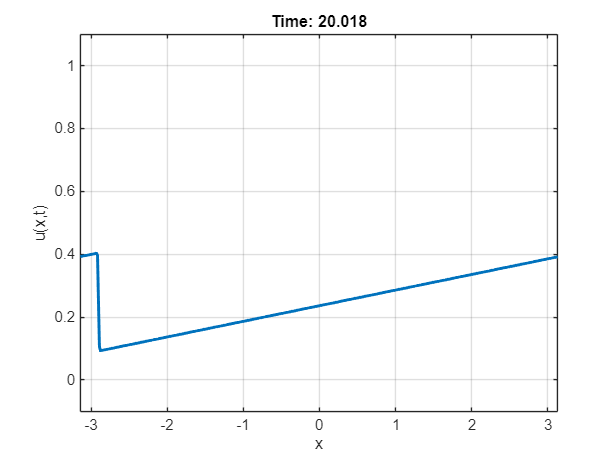

% plotting
padding = 0.10*(max(u0)-min(u0));

f = figure();

for i = 1:length(T)
    plot(X, U(i,:), '-', 'LineWidth', 2);
    title(sprintf('Time: %.3f', T(i)));
    grid on;
    xlabel('x');
    xlim([min(X),max(X)]);
    ylabel('u(x,t)');
    ylim([min(u0)-padding,max(u0)+padding]);
    pause(0.01);
end